resonance_freq = 5.7851e9;
detuning = linspace(-10e6,2e6,1000);
% kerr = find_kerr_MHz_ng_flux(0, 0) *1e6;
kerr = -0.1e6

kerr = -100000

kappa_ext = 1.2323e6;
kappa_int = .22653e6;
% kappa_ext = 1.271e6;
% kappa_int = .15e6;
kappa_tot = kappa_int + kappa_ext;
h = 6.626e-34;
if kerr > 0 
    if sqrt(3)/2*kappa_tot > detuning
        disp('no bifurcations')
        return
    end
elseif kerr < 0 
    if sqrt(3)/2*kappa_tot < detuning
        disp('no bifurcations')
        return
    end
end

$P_{in,b_1}, P_{in, b_2} = \frac{2}{27} \frac{\Delta^3}{K}\big[\big(1+\frac{9\kappa_{tot}^2}{4\Delta^2} \big) \mp \big(1 - \frac{3\kappa_{tot}^2}{4\Delta^2}\big)^{3/2}\big]\frac{\hbar\omega_d}{\kappa_{ext}}$, see page 5 of kerr solver notes, corresponds to equation 2.13 Vijay thesis, eqn. 49 of PRB 2013 Wustmann

bifurcation_power_1_watts = 2/27.*detuning.^3./kerr.*((1+9*kappa_tot^2/4./detuning.^2)+(1-3*kappa_tot^2/4./detuning.^2).^1.5)*h*resonance_freq/kappa_ext;
bifurcation_power_2_watts = 2/27.*detuning.^3/kerr.*((1+9*kappa_tot^2/4./detuning.^2)-(1-3*kappa_tot^2/4./detuning.^2).^1.5)*h*resonance_freq/kappa_ext;

bifurcation_power_1_dBm = 10.*log10(bifurcation_power_1_watts./1e-3);
bifurcation_power_2_dBm = 10.*log10(bifurcation_power_2_watts./1e-3);

bifurcation_power_1_dBm(imag(bifurcation_power_1_watts) ~=0) = nan;
bifurcation_power_2_dBm(imag(bifurcation_power_2_watts) ~=0) = nan;
bifurcation_power_1_watts(imag(bifurcation_power_1_watts) ~=0) = nan;
bifurcation_power_2_watts(imag(bifurcation_power_2_watts) ~=0) = nan;

bifurcation_power_1_dBm(bifurcation_power_1_watts<0) = nan;
bifurcation_power_2_dBm(bifurcation_power_2_watts<0) = nan;
bifurcation_power_1_watts(bifurcation_power_1_watts<0) = nan;
bifurcation_power_2_watts(bifurcation_power_2_watts<0) = nan;

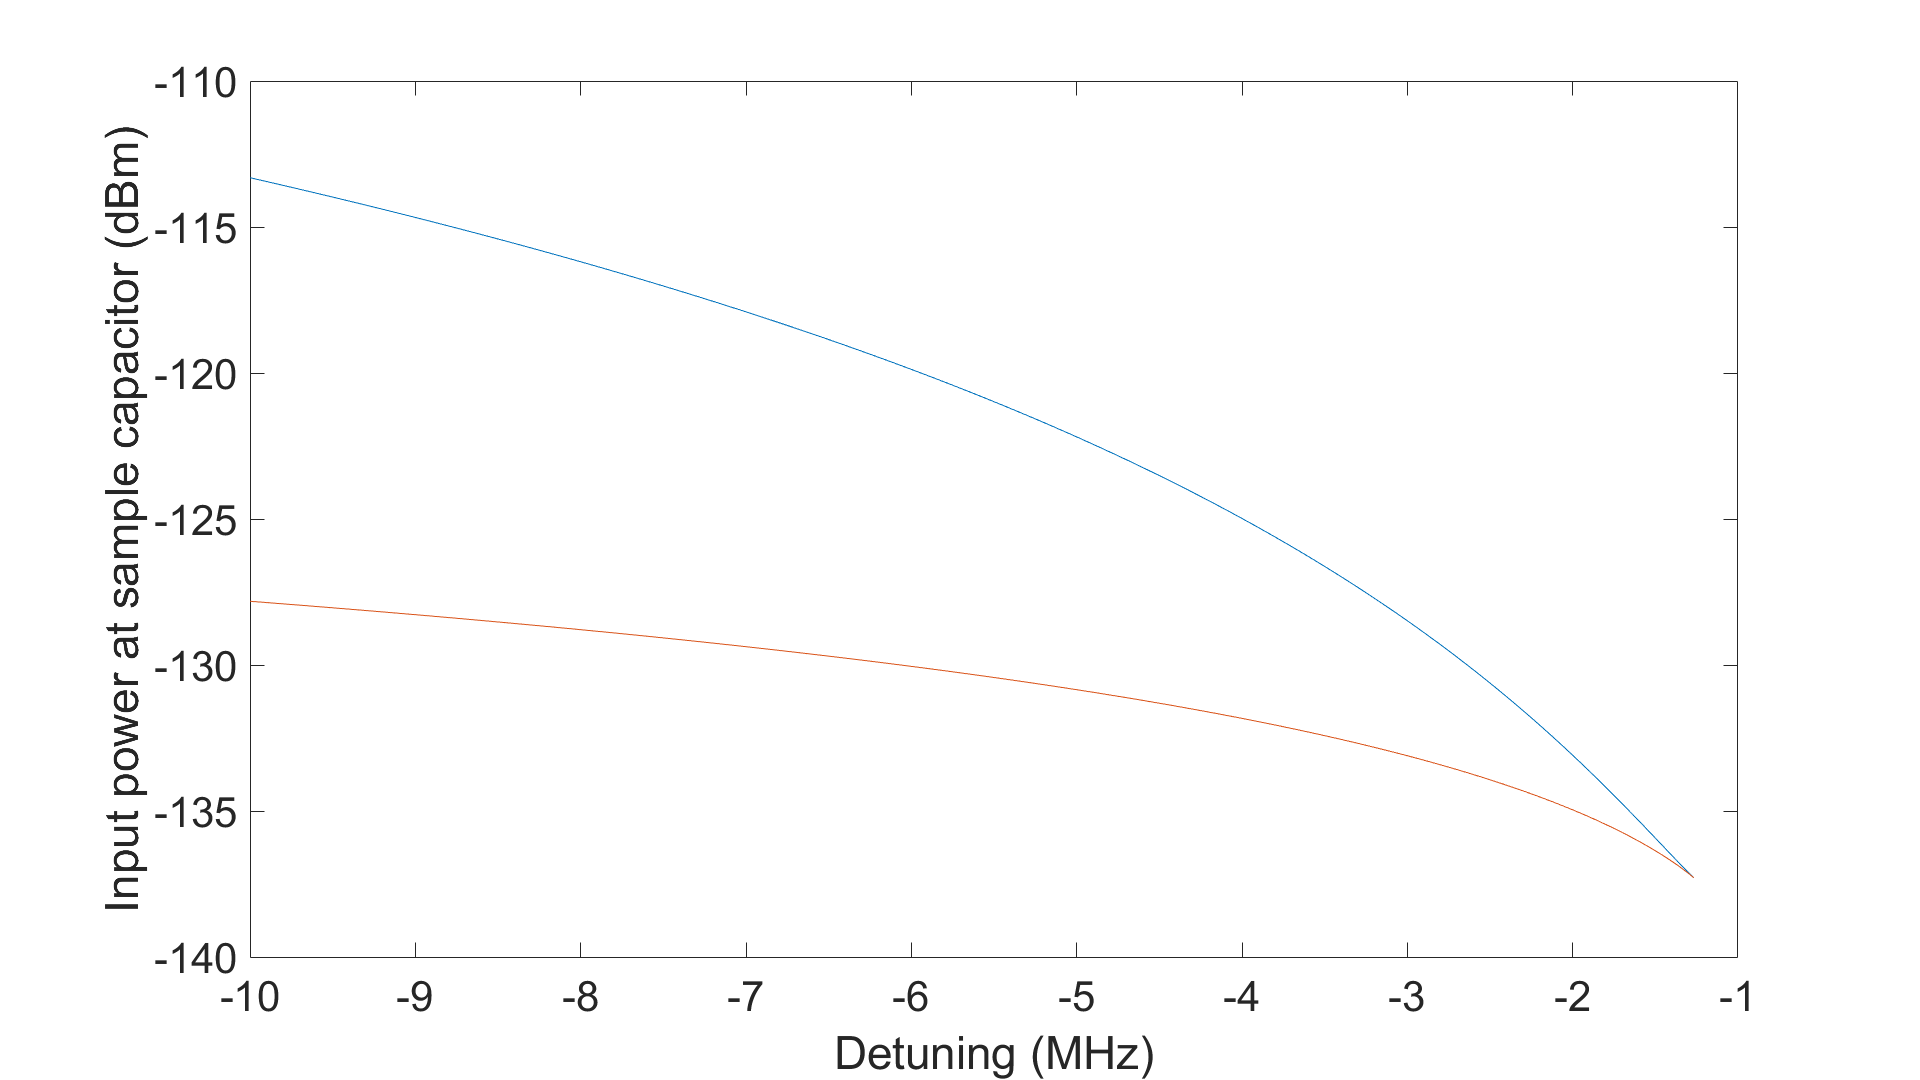

figure
plot(detuning/1e6, bifurcation_power_1_dBm, 'DisplayName', 'Upper bifurcation power')
hold on
plot(detuning/1e6, bifurcation_power_2_dBm,'DisplayName', 'Lower bifurcation power')
xlabel('Detuning (MHz)')
ylabel('Input power at sample capacitor (dBm)')

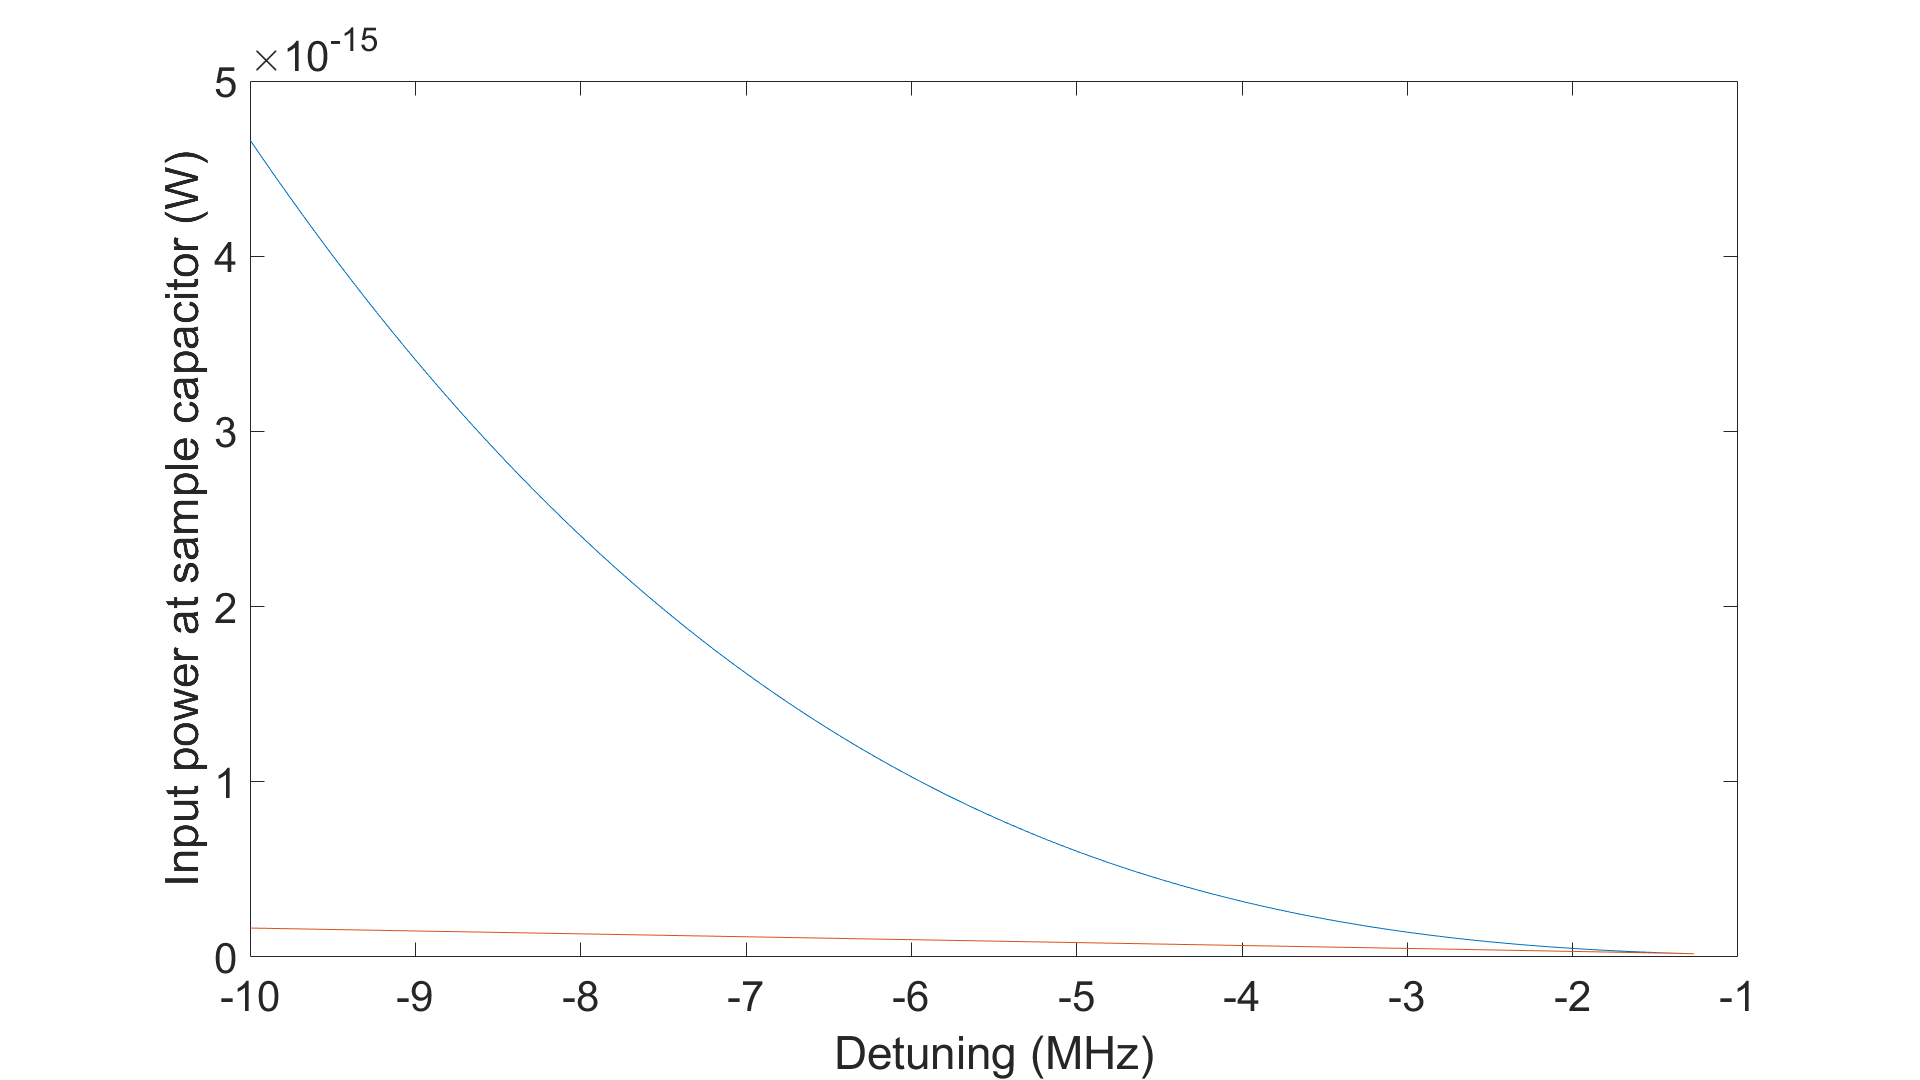

figure
plot(detuning/1e6, 1e-3*10.^(bifurcation_power_1_dBm/10), 'DisplayName', 'Upper bifurcation power')
hold on
plot(detuning/1e6, 1e-3*10.^(bifurcation_power_2_dBm/10),'DisplayName', 'Lower bifurcation power')
xlabel('Detuning (MHz)')
ylabel('Input power at sample capacitor (W)')